# Approximation and detail decomposition with `wrcoef`

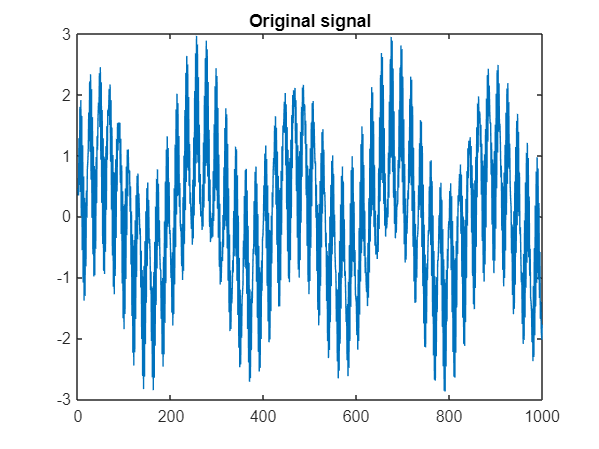

load sumsin
ydata = sumsin';
figure
plot(ydata)
title("Original signal")

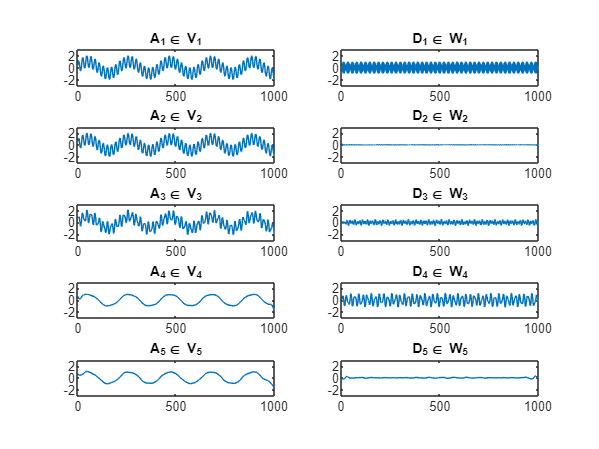


% Perform a 5-level wavelet decomposition of the signal using db4 Daubechies wavelet.
J = 5;
[C,L] = wavedec(ydata, J,'db4');

%  Extract the coarse scale approximation
figure
A = zeros(numel(ydata), J);
D = zeros(numel(ydata), J);
for j = 1:J
    A(:,j) = wrcoef('a', C,L,'db4',j);   % approximation = progection on V_j
    D(:,j) = wrcoef('d', C,L,'db4',j);   % detail = projection on W_j

    subplot(J,2,2*j-1)
    plot(A(:,j))
    ylim([-3 3]), title("A_"+j+"\in V_"+j)
    
    subplot(J,2,2*j)
    plot(D(:,j))
    ylim([-3 3]), title("D_"+j+"\in W_"+j)
end

whos A D

  Name         Size            Bytes  Class     Attributes

  A         1000x5             40000  double              
  D         1000x5             40000  double              



Check approximation errors:


$$f\simeq A_1 +D_1$$
  


$$A_j \simeq A_{j+1} +D_{j+1}$$


err1 = max(abs(ydata - (A(:,1) + D(:,1))));    % f = A1 + D1
disp("f = A1 + D1, with error " +err1)

f = A1 + D1, with error 7.3537e-12


err2 = max(abs(A(:,1) - (A(:,2) + D(:,2))));   % A1 = A2 + D2
disp("A1 = A2 + D2, with error "+err2)

A1 = A2 + D2, with error 4.4409e-16


err3 = max(abs(A(:,2) - (A(:,3) + D(:,3))));  % A2 = A3 + D3
disp("A2 = A3 + D3, with error "+err3)

A2 = A3 + D3, with error 8.8818e-16


err4 = max(abs(A(:,3) - (A(:,4) + D(:,4))));  % A3 = A4 + D4
disp("A3 = A4 + D4, with error "+err4)

A3 = A4 + D4, with error 1.1102e-15


err5 = max(abs(A(:,4) - (A(:,5) + D(:,5))));   % A4 = A5 + D5
disp("A4 = A5 + D5, with error "+err5)

A4 = A5 + D5, with error 1.3323e-15


Check total error at level J = 5 in 


$$f\approx \mathrm{A5}+\mathrm{D1}+\mathrm{D2}+\ldotp \ldotp \ldotp +\mathrm{D5}$$


total_error = max(abs(ydata - (A(:,end) + sum(D,2))))

total_error = 7.3532e-12

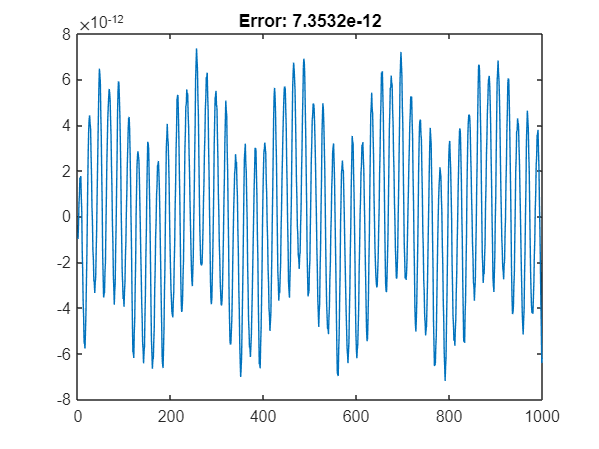


%figure
error = ydata - (A(:,5) + sum(D,2));
figure
plot(error)
title ("Error: " + total_error) 

for j = 1:J
    APP{:,j} = appcoef(C,L,'db4',j);
    DET{:,j} = detcoef(C,L,j);
end
L

L =           38
          38
          69
         131
         255
         503
        1000


APP

APP = 1×5 cell array
    {503×1 double}    {255×1 double}    {131×1 double}    {69×1 double}    {38×1 double}


DET

DET = 1×5 cell array
    {503×1 double}    {255×1 double}    {131×1 double}    {69×1 double}    {38×1 double}


% Extract approximation at level 5
A5 = appcoef(C,L,'db4',5);

% Extract only one detail signal at a specific level
D5 = detcoef(C,L,5);
% Extract all detail signals
[D1,D2,D3,D4,D5] = detcoef(C,L,1:5);
whos A5 D5 D4 D3 D2 D1

  Name        Size            Bytes  Class     Attributes

  A5         38x1               304  double              
  D1        503x1              4024  double              
  D2        255x1              2040  double              
  D3        131x1              1048  double              
  D4         69x1               552  double              
  D5         38x1               304  double              

